# Segmenting Based on Average Color in a Region of Interest

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

oranges = imread("./images/orangeTree.jpg");
LAB = rgb2lab(oranges);
a = LAB(:, :, 2);
b = LAB(:, :, 3);
BW = logical(readmatrix("./images/orangeMask.csv", OutputType="uint8"));

## Task 1

To find the average color in the region of interest, you must first extract the pixel intensities in that region. You can use a mask to do this.

`M` `=` `[``1` `2` `3``;``4` `5` `6``]``;`

`BW` `=` `[``true` `false` `true``;` `true` `false` `true``]``;`

`M``(``BW``)` `=` 

`ans` `=` 

          `1`

          `4`

          `3`

          `6`

The indexing occurs columnwise. The result is a vector containing all of the values where the mask is true.

aROI = a(BW);
bROI = b(BW);

## Task 2

meanROI = [mean(aROI) mean(bROI)];

## Task 3

You can calculate distance between all of the pixels in the a* and b* planes using the distance formula.


$$\sqrt{{\left(a^* -a_{\mathrm{mean}} \right)}^2 +{\left(b^* -b_{\mathrm{mean}} \right)}^2 }$$


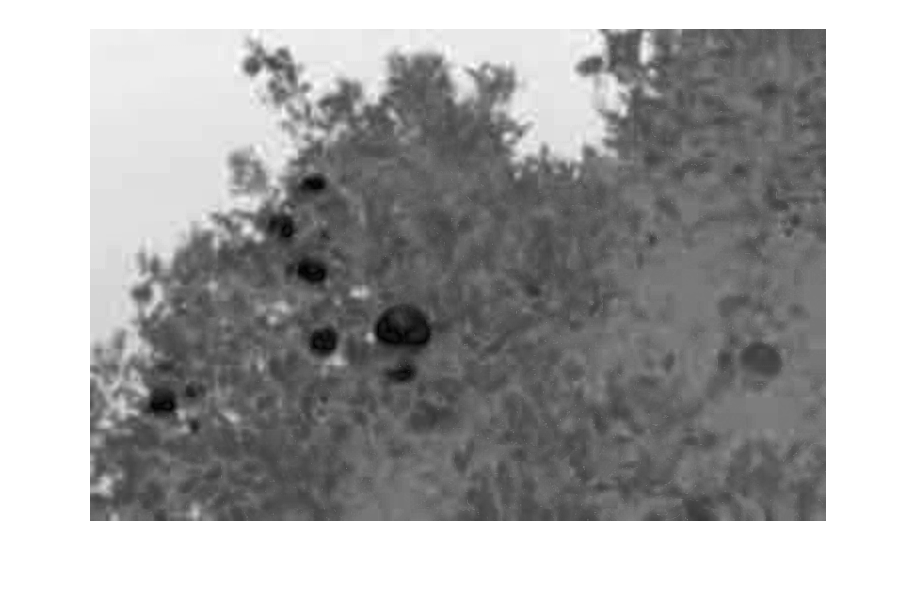

distLab = sqrt((a - meanROI(1)).^2 + (b - meanROI(2)).^2);
imshow(distLab, [])

## Task 4

Dark regions of `distLab` represent colors that are close, or similar, to the color of the region of interest and bright regions are dissimilar colors.

orangeMask = distLab < 25;

## Task 5

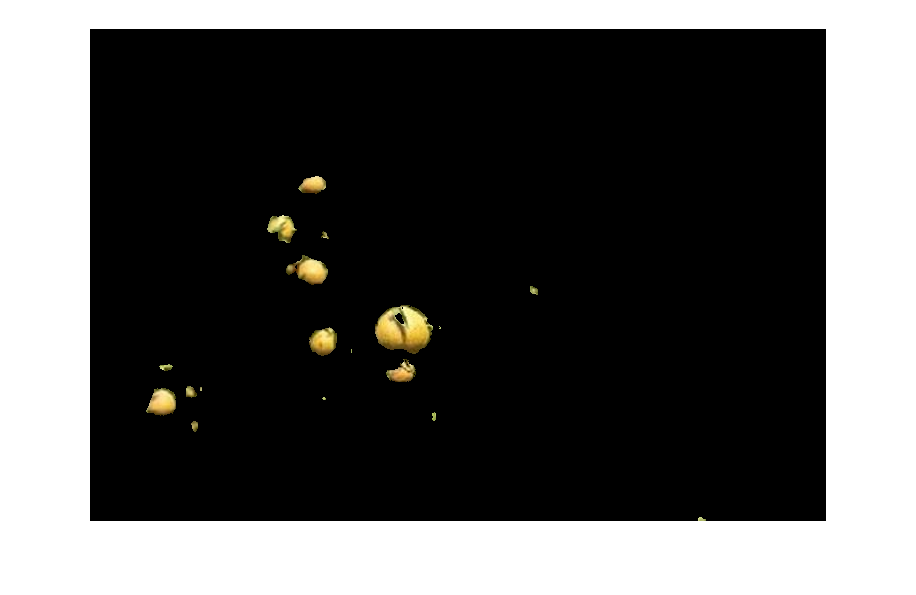

LabOranges  = imoverlay(oranges, ~orangeMask, "k");
imshow(LabOranges)